# **JacobiTheta**

[Jacobi Theta functions](https://dlmf.nist.gov/20)

## Definition


$$\vartheta_1 \left(x,q\right)\equiv 2\sum_{n=0}^{\infty } {\left(-1\right)}^n q^{{\left(n+\frac{1}{2}\right)}^2 } \mathrm{sin}\left(\left(2n+1\right)x\right)$$



$$\vartheta_2 \left(x,q\right)\equiv 2\sum_{n=0}^{\infty } q^{{\left(n+\frac{1}{2}\right)}^2 } \mathrm{cos}\left(\left(2n+1\right)x\right)$$



$$\vartheta_3 \left(x,q\right)\equiv 1+2\sum_{n=0}^{\infty } q^{n^2 } \mathrm{cos}\left(2n\;x\right)$$



$$\vartheta_4 \left(x,q\right)\equiv 1+2\sum_{n=0}^{\infty } {\left(-1\right)}^n q^{n^2 } \mathrm{cos}\left(2n\;x\right)$$


where q is the nome.

Domain:  $0\le q<1\;$, $-\infty <x<\infty$.   For the specified domain, the  codomain  is the set of real numbers.

Basic features:

Special values:

$\vartheta_1 \left(0,q\right)=0$,  $\vartheta_1 \left(x,0\right)=0$,  $\vartheta_1 \left(\frac{\pi }{2}\left(2n+1\right),q\right)=\vartheta_1 \left(\pi n,q\right)$

$\vartheta_2 \left(x,0\right)=0$,    $\vartheta_3 \left(x,0\right)=1$,    $\vartheta_4 \left(x,0\right)=1$

Identities:

## Syntax

Y = JacobiTheta1(X,Q)

Y = JacobiTheta2(X,Q)

Y = JacobiTheta3(X,Q)

Y = JacobiTheta4(X,Q)

y = jtheta1(x,q)

y = jtheta2(x,q)

y = jtheta3(x,q)

y = jtheta4(x,q)

## Description

**Y = JacobiThetaN(X,Q)** returna the Jacobi theta function thetaN for each element of the arrays X and Q (nome). X and Q must be real and the sdne size or any of them can be scalar. JacobiThetaN is the wrapper function which calls the functions **jtheta** element-wise via the function **ufun2**.

**y = jthetaN(x,q)** return the value of the Jacobi theta function thetaN  for argument *x* and the nome q. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed. **jthetaN** is the wrapper function which calls the functions **jtheta **for the actual calculation.  **jtheta **is the MATLAB translation of the Pascal procedure **jacobi_theta** from AMath [1].

## Precision

## **Numerical Examples**

**Scalar input**

Accuracy

format long
q = 0.5;
x = 0.5;
[jtheta0(1,x,q), JacobiTheta1(x,q),jtheta0(2,x,q), JacobiTheta2(x,q)]

ans =    0.402768575854814   0.402768575854814   1.484216087659583   1.484216087659583


% Maple 0.402768575854814_315    1.484216087659583_11

[jtheta0(3,x,q), JacobiTheta3(x,q),jtheta0(4,x,q), JacobiTheta4(x,q)]

ans =    1.484396862425167   1.484396862425167   0.411526533253405   0.411526533253405


% Maple 1.484396862425166_93    0.411526533253405_515


Special values

[jtheta0(1,x,0),jtheta0(2,x,0),jtheta0(3,x,0),jtheta0(4,x,0)]

ans =      0     0     1     1


n=2;
q = 0.5;
disp(jtheta0(1,pi/2*(2*n+1),q)-jtheta0(2,pi*n,q))

     2.220446049250313e-15



**Vector input**

n=2;
Q = [0.1, 0.2, 0.5];
disp(JacobiTheta1(pi/2*(2*n+1),Q)-JacobiTheta2(pi*n,Q))

   1.0e-14 *

                   0                   0   0.222044604925031



**Matrix input**

n=2;
Q = [0.1, 0.2; -0.1, 0.5];
disp(JacobiTheta1(pi/2*(2*n+1),Q)-JacobiTheta2(pi*n,Q))

   1.0e-14 *

                   0                   0
                 NaN   0.222044604925031



## **Plot **

**Example 1**

[NIST Fig 20.3.1-20.3.5](https://dlmf.nist.gov/20.3)

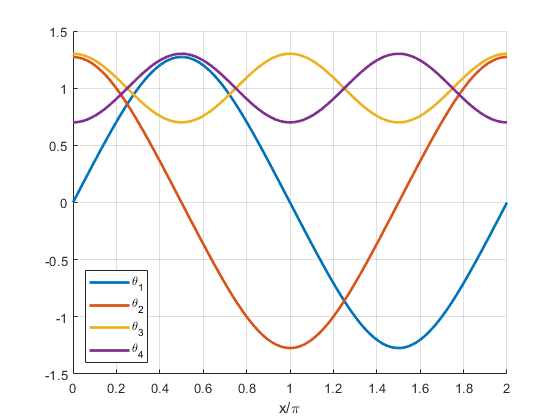

npts = 600;
q = [0.05, 0.5, 0.7, 0.9];

x = linspace( 0, 2, npts);
xx = pi*x;

figure(1)
clf
hold on
qq = 0.15;
plot(x,JacobiTheta1(xx,qq),'LineWidth',2)
plot(x,JacobiTheta2(xx,qq),'LineWidth',2)
plot(x,JacobiTheta3(xx,qq),'LineWidth',2)
plot(x,JacobiTheta4(xx,qq),'LineWidth',2)
hlg = legend('\theta_1','\theta_2','\theta_3','\theta_4','Location','best');
%title(hlg, strcat('q = ',num2str(q(n),6)),'FontWeight','normal')
xlabel('x/\pi')
ylim([-1.5,1.5]);
grid on
hold off

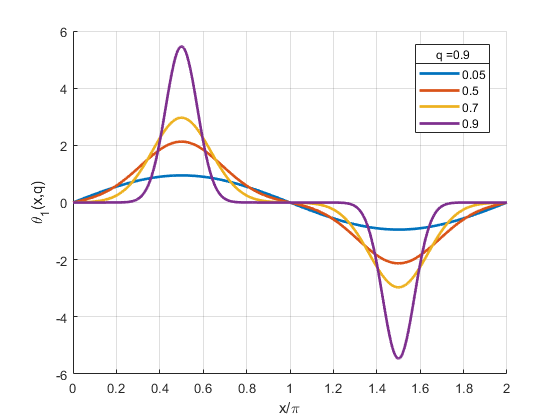

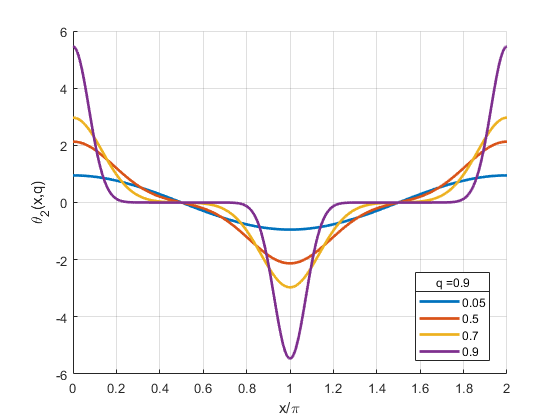

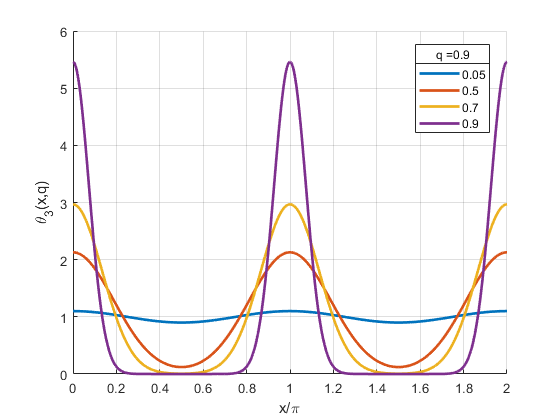

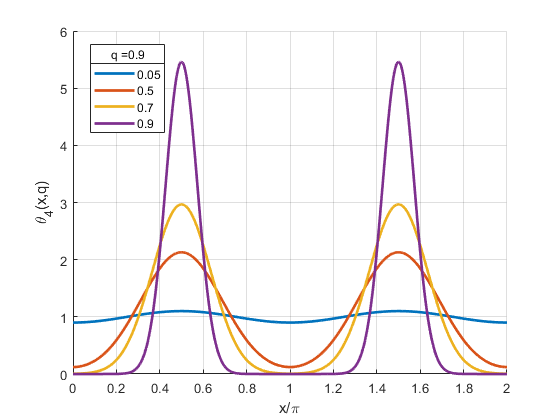

for m = 1:4
    figure(m+1)
    clf
    hold on
    for n = 1:length(q)
        switch m
            case 1
                ylabel('\theta_1(x,q)')
                y= JacobiTheta1(xx,q(n));
            case 2
                 ylabel('\theta_2(x,q)')
                y = JacobiTheta2(xx,q(n));
            case 3
                 ylabel('\theta_3(x,q)')
                y = JacobiTheta3(xx,q(n));
            case 4
                 ylabel('\theta_4(x,q)')
                y = JacobiTheta4(xx,q(n));
        end
        plot(x,y,'LineWidth',2)
    end
    hlg = legend('0.05','0.5','0.7','0.9','Location','best');
    title(hlg, strcat('q = ',num2str(q(n),6)),'FontWeight','normal')
    xlabel('x/\pi')
    if m <= 2
        ylim([-6,6]);
    else
        ylim([0, 6]);
    end
    grid on
    hold off
end

**Example 2**

[NIST Fig 20.3.6-20.3.9](https://dlmf.nist.gov/20.3)

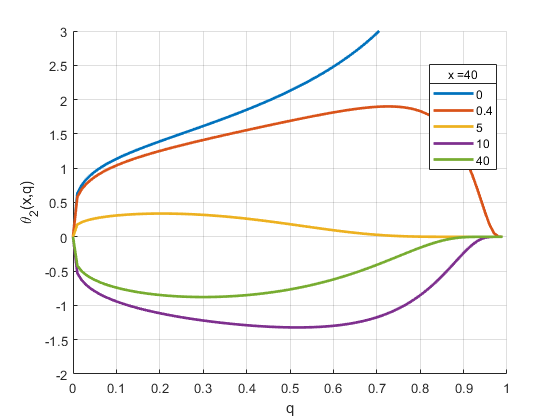

ans = 4

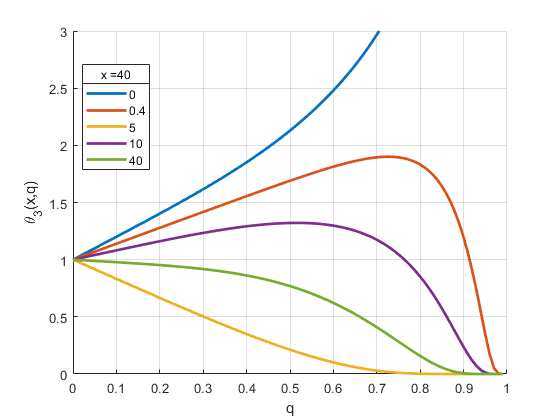

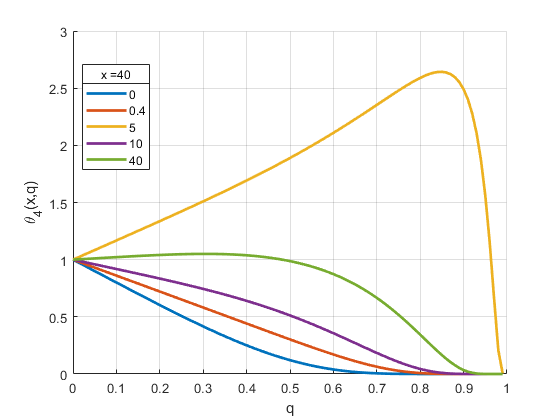

q = 0:0.01:1;
xx = [0, 0.4, 5, 10, 40];
for m = 1:4
    figure(m+1)
    clf
    hold on
    for n = 1:length(xx)
        switch m
            case 1
                ylabel('\theta_1(x,q)')
                y= JacobiTheta1(xx(n),q);
            case 2
                ylabel('\theta_2(x,q)')
                y = JacobiTheta2(xx(n),q);
            case 3
                ylabel('\theta_3(x,q)')
                y = JacobiTheta3(xx(n),q);
            case 4
                ylabel('\theta_4(x,q)')
                y = JacobiTheta4(xx(n),q);
        end
        plot(q,y,'LineWidth',2)
    end
    hlg = legend('0','0.4','5','10','40','Location','best');
    title(hlg, strcat('x = ',num2str(xx(n),6)),'FontWeight','normal')
    xlabel('q')
    switch m
        case 1
            ylim([-3,1.5]);
        case 2
            ylim([-2,3])
        case 3,4
            ylim([0, 3]);
    end
    grid on
    hold off
end

**Example 3**

[NIST Fig 20.3.10-20.3.13](https://dlmf.nist.gov/20.3)

ans = 2

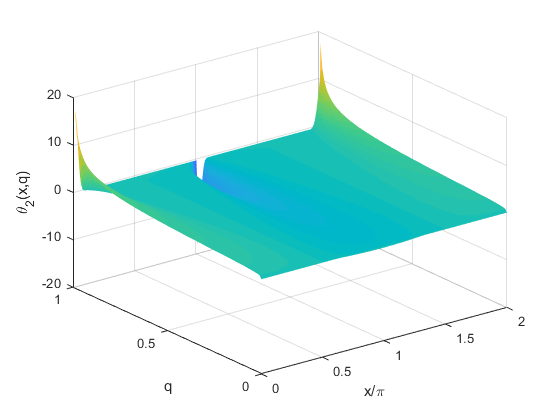

ans = 4

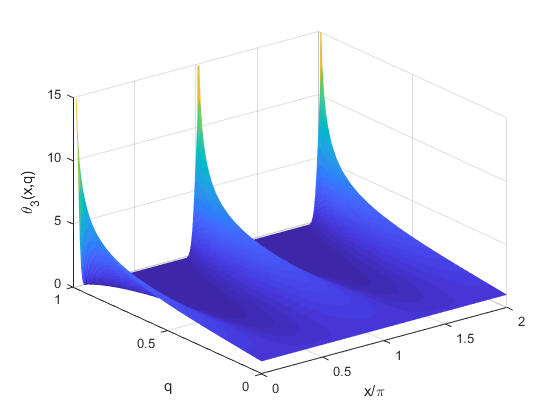

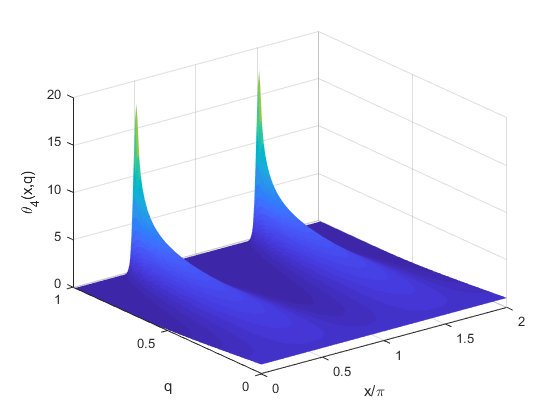

q = 0:0.01:0.99;
x = 0:0.01:2;
zz = 15;
[X,Q] = meshgrid(x,q);
for m = 1:4
    figure(m+1)
    clf
    hold on
    switch m
        case 1
            zlabel('\theta_1(x,q)')
            Z= JacobiTheta1(pi*X,Q);
        case 2
            zlabel('\theta_2(x,q)')
            Z= JacobiTheta2(pi*X,Q);
        case 3
            zlabel('\theta_3(x,q)')
            Z= JacobiTheta3(pi*X,Q);
        case 4
            zlabel('\theta_4(x,q)')
            Z= JacobiTheta4(pi*X,Q);
    end
    surf(X,Q,Z,'EdgeColor','none');
    view(3)
    ylabel('q')
    xlabel('x/\pi')
    switch m
        case 1,2
            zlim([-zz,zz]);
            caxis([-zz zz])
        case 3,4
            zlim([0, zz]);
            caxis([0 zz])
    end
    grid on
    hold off
end

**Example 4**

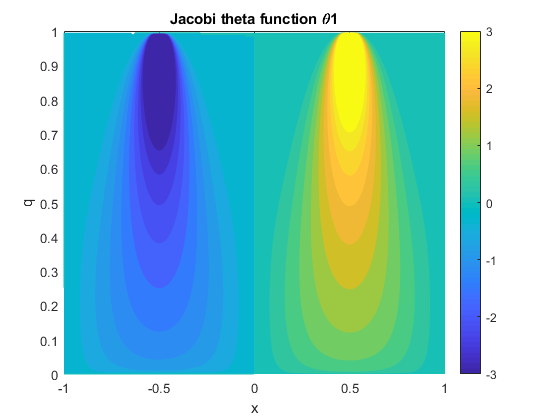

figure
f = @(x,q)JacobiTheta1(pi*x,q);
fcontour(f,[-1 1 0 1],'Fill','on','LevelList',-3:0.3:3,'MeshDensity',200)
title('Jacobi theta function \theta1')
colorbar
xlabel('x')
ylabel('q')
grid on

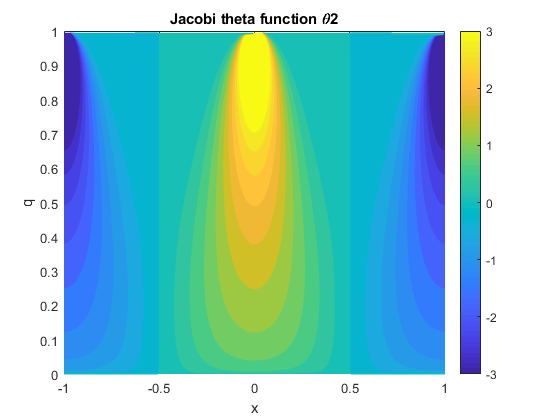

figure
f = @(x,q)JacobiTheta2(pi*x,q);
fcontour(f,[-1 1 0 1],'Fill','on','LevelList',-3:0.3:3,'MeshDensity',200)
title('Jacobi theta function \theta2')
colorbar
xlabel('x')
ylabel('q')
grid on

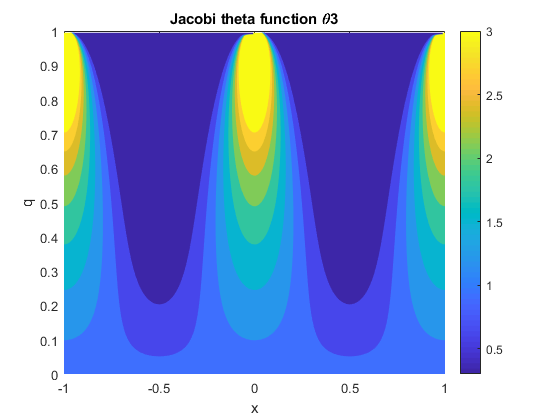

figure
f = @(x,q)JacobiTheta3(pi*x,q);
fcontour(f,[-1 1 0 1],'Fill','on','LevelList',-3:0.3:3,'MeshDensity',200)
title('Jacobi theta function \theta3')
colorbar
xlabel('x')
ylabel('q')
grid on

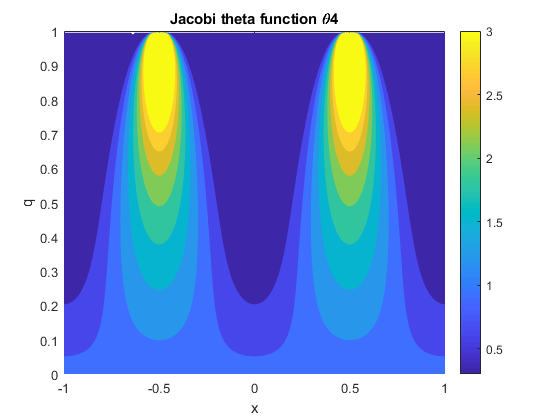

figure
f = @(x,q)JacobiTheta4(pi*x,q);
fcontour(f,[-1 1 0 1],'Fill','on','LevelList',-3:0.3:3,'MeshDensity',200)
title('Jacobi theta function \theta4')
colorbar
xlabel('x')
ylabel('q')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Theta Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/20)

[Theta function, Wikipedia](https://en.wikipedia.org/wiki/Theta_function)

## **References**

[1] W.Ehrhardt, "The AMath and DMath Special functions", 2016

## See Also